# Create and Customize semilogx Plots 

Semilog plot (x-axis has log scale)

### Create Data

Use *logspace*, *linspace* and *exp* functions in a helper function to generate vectors of points for some hypothetical measured and estimated data.

[x,yMeasured,yEstimated] = createData();

### Basic semilogx Plot

Plot estimated and measured data with a logarithmic x-axis using `semilogx`.

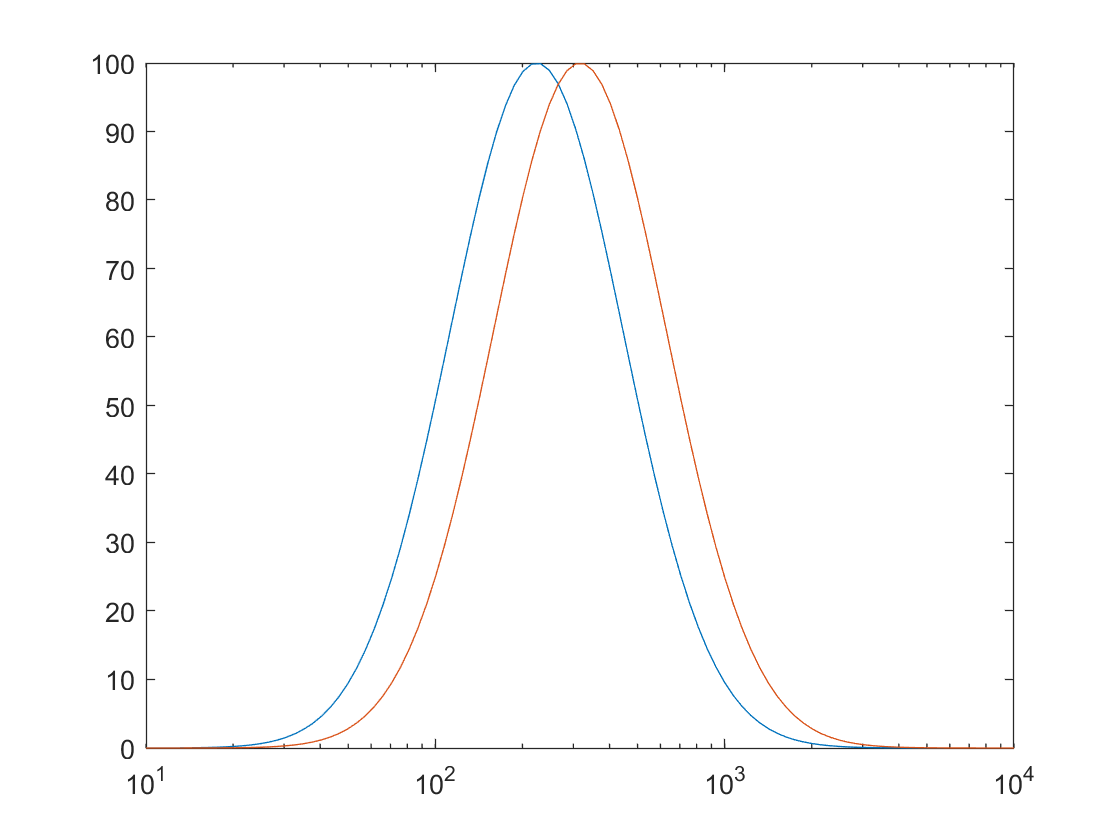

semilogx(x,yMeasured,x,yEstimated)

## Customization

### Customize Line Appearance

Specify the line type and line color to use for the estimated data to distinguish it from measured data.

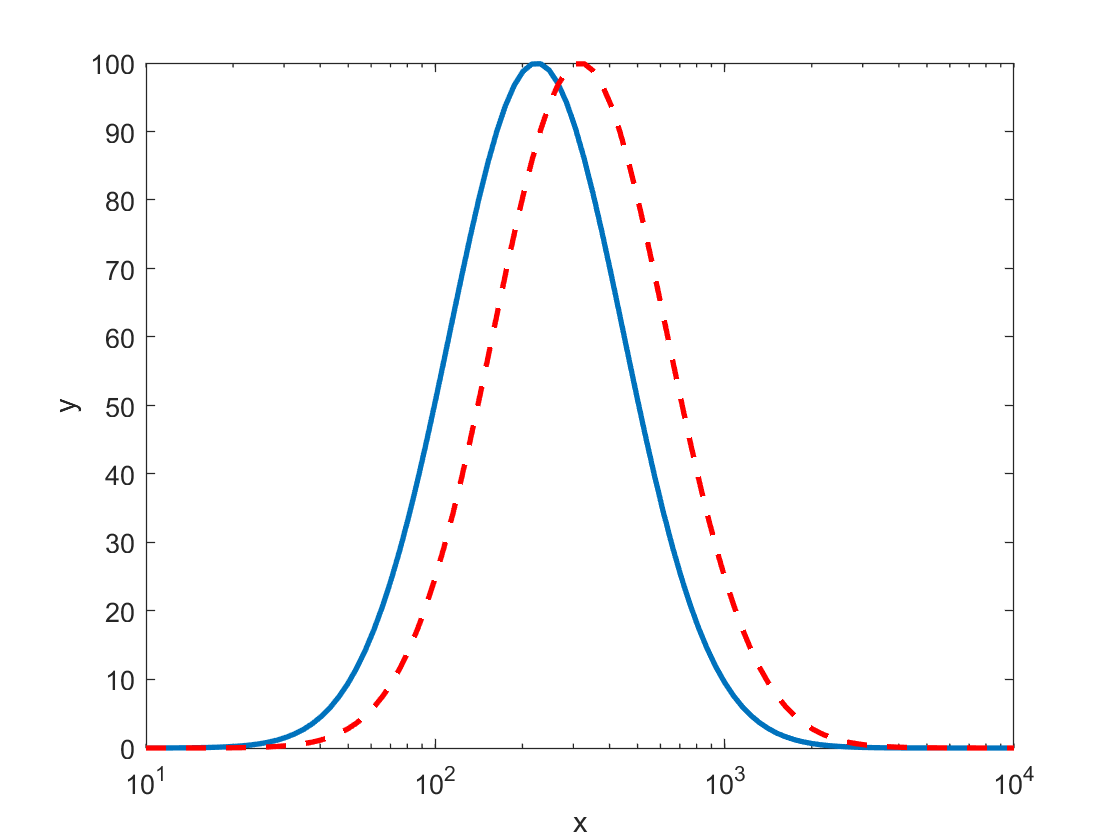

LineType = '--';
LineColor = 'r';
LineWidth = 2;

s = semilogx(x,yMeasured,x,yEstimated,...
    [LineType LineColor],...    % Specify line type and color
    "LineWidth",LineWidth);     % Specify line width
xlabel("x")
ylabel("y")

### Add a Legend and a Grid

Use the grid with `semilogx` to clearly display the logarithmic axis and add a legend to label the plot lines.

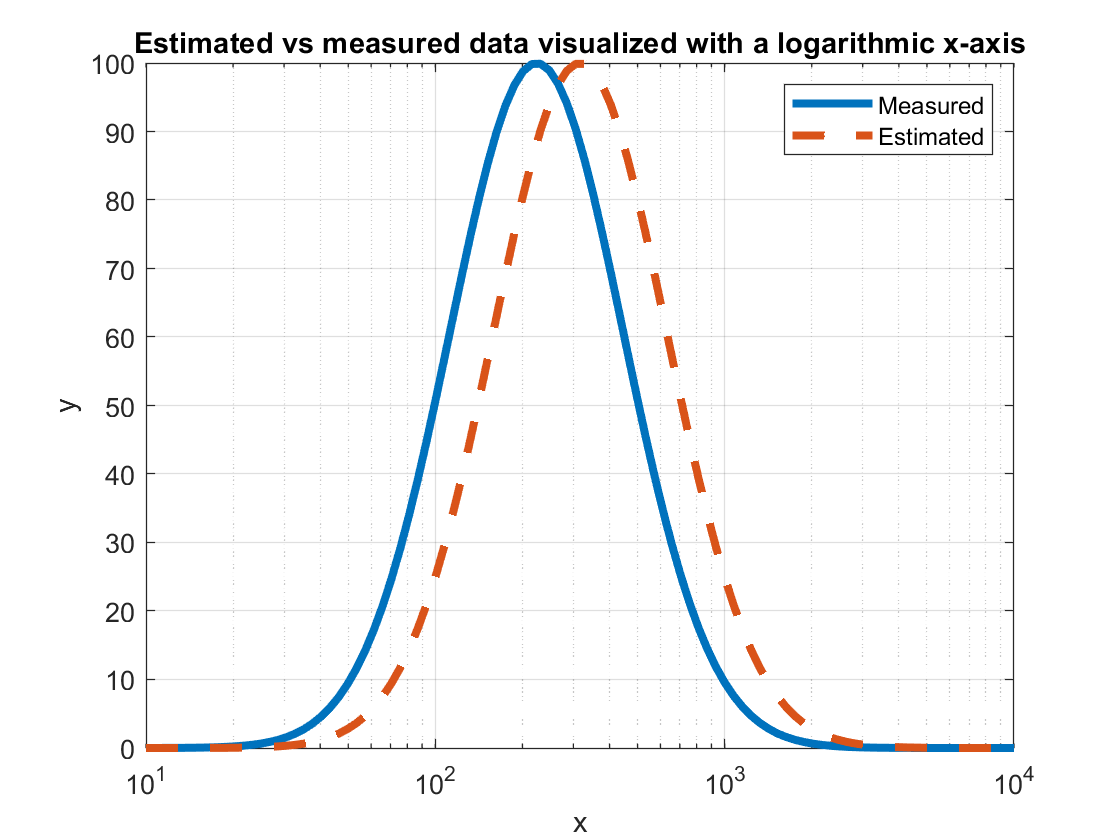

figure
s1 = semilogx(x,yMeasured,x,yEstimated,...
    "--",...        % Specify a dashed line for the second line 
    "LineWidth",3); % Specify line width for both lines
legend("Measured","Estimated")
grid on
xlabel("x")
ylabel("y")
title("Estimated vs measured data visualized with a logarithmic x-axis")

## **Additional Information**

### **Get All Line Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Line, uncomment the following code. View or modify these properties using dot notation.

% get(s(1))

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[semilogx](https://www.mathworks.com/help/matlab/ref/semilogx.html)

### Helper Functions

This function generates estimated and measured y data.

function [x,yMeasured,yEstimated] = createData()
    x = logspace(1,4,100);
    v = linspace(-50,50,100);
    yMeasured = 100*exp(-1*((v+5).^2)./200);
    yEstimated = 100*exp(-1*(v.^2)./200);
end

Copyright (c) 2021, The MathWorks, Inc.